**Creating artificial x- and y-data**

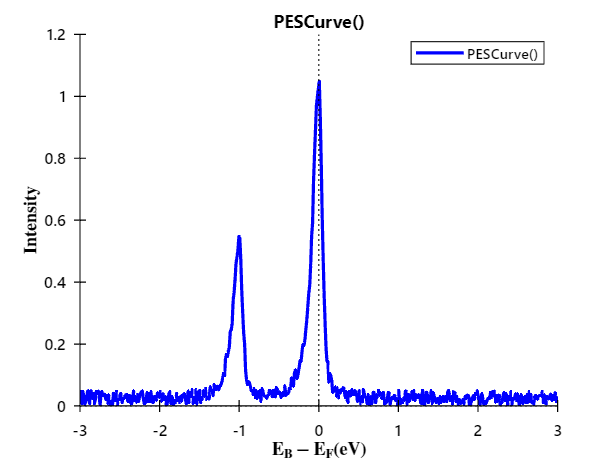

close all; clear all;
% Generate Random 1D data to be fitted
xdat = linspace(-3, 3, 5e2);
TYPE    = "sGLA";   % type of curve to use for fitting. Default: "sGLA" ("pGLA", "sGL", "pGL", "G", "L", "DS")
BE      =  0.0;      % scalar of the binding energy of PE curve.
INT     =  1.0;      % scalar of the peak intensity of PE curve.
FWHM    =  0.1;     % scalar of the FWHM of the PE curve.
MR      =  0.5;     % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSX     = -1.0;     % scalar of the binding energy of spin-orbit split PE curve.
LSY     =  0.5;     % calar of the branching ratio of spin-orbit split PE curve.
LSW     =  0.0;     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     =  0.1;     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
% 2 - Calculating the lineshape
ydat    = PESCurve(xdat, TYPE, BE, INT, FWHM, MR, LSX, LSY, LSW, ASY);
ydat    = ydat + 0.05*rand(size(ydat));
% 3 - Plotting the lineshapes & verifying the FWHM values
figure(); plot(xdat, ydat, 'b-', 'linewidth', 2);
gca_props(); title('PESCurve()', 'Interpreter','none'); 
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity $$', 'Interpreter', 'latex');
legend({'PESCurve()'}, 'location', 'best', 'Interpreter','none');

# **(1) - 1D Curve Fitting - N curves, no background**

**(1.1) Defining the initial conditions, boundaries and model**

% DEFINING THE TYPES OF CURVES TO BE USED
curve_type = "sGLA";       % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")

% 1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
XLOC    = [0; -1];          % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
YINT    = [0.5; 0.2];       % scalar of the peak intensity of PE curve.
FWHM    = [0.1; 0.1];       % scalar of the FWHM of the PE curve.
MR      = [0.7; 0.3];       % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
ASY     = [0.05; 0.05];     % scalar of the asymmetry parameter.
init_params{1} = [XLOC, YINT, FWHM, MR, ASY]; 
init_params{1}

ans =          0    0.5000    0.1000    0.7000    0.0500
   -1.0000    0.2000    0.1000    0.3000    0.0500



% 2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
init_params{2} = init_params{1}; 
init_params{2}(:,1) = init_params{1}(:,1) - 0.25;
init_params{2}(:,2) = init_params{1}(:,2) - 1.00;
init_params{2}(:,3) = init_params{1}(:,3) - 0.25;
init_params{2}(:,4) = init_params{1}(:,4) - 0.50;
init_params{2}(:,5) = init_params{1}(:,5) - 0.10;
init_params{2}

ans =    -0.2500   -0.5000   -0.1500    0.2000   -0.0500
   -1.2500   -0.8000   -0.1500   -0.2000   -0.0500


% -- Upper bounds
init_params{3}      = init_params{1}; 
init_params{3}(:,1) = init_params{1}(:,1) + 0.25;
init_params{3}(:,2) = init_params{1}(:,2) + 0.75;
init_params{3}(:,3) = init_params{1}(:,3) + 0.25; 
init_params{3}(:,4) = init_params{1}(:,4) + 0.50; 
init_params{3}(:,5) = init_params{1}(:,5) + 0.10;
init_params{3}

ans =     0.2500    1.2500    0.3500    1.2000    0.1500
   -0.7500    0.9500    0.3500    0.8000    0.1500



% 3 - Preview the initial model fit
curvefit1D_view_init(xdat, ydat, curve_type, init_params);

Error using PESBackground
Too many input arguments.

Error in curvefit1D_view_init (line 76)
[X, D, B] = PESBackground(xdat, ydat,...

**(1.2) Execute fitting algorithm**

fitStr = curvefit1D_solver(xdat, ydat, curve_type, init_params); fitStr
curvefit1D_view_fit(fitStr);

# **(2) - 1D Curve Fitting - N curves, with background**

**(2.1) Defining the initial conditions, boundaries and model**

% DEFINING THE TYPES OF CURVES TO BE USED
curve_type = "sGLA";       % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")

% 1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
XLOC    = [0; -1];          % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
YINT    = [0.5; 0.2];       % scalar of the peak intensity of PE curve.
FWHM    = [0.1; 0.1];       % scalar of the FWHM of the PE curve.
MR      = [0.7; 0.3];       % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
ASY     = [0.05; 0.05];     % scalar of the asymmetry parameter.
init_params{1} = [XLOC, YINT, FWHM, MR, ASY]; 
init_params{1}

% 2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
init_params{2} = init_params{1}; 
init_params{2}(:,1) = init_params{1}(:,1) - 0.25;
init_params{2}(:,2) = init_params{1}(:,2) - 1.00;
init_params{2}(:,3) = init_params{1}(:,3) - 0.25;
init_params{2}(:,4) = init_params{1}(:,4) - 0.50;
init_params{2}(:,5) = init_params{1}(:,5) - 0.10;
init_params{2}
% -- Upper bounds
init_params{3}      = init_params{1}; 
init_params{3}(:,1) = init_params{1}(:,1) + 0.25;
init_params{3}(:,2) = init_params{1}(:,2) + 0.75;
init_params{3}(:,3) = init_params{1}(:,3) + 0.25; 
init_params{3}(:,4) = init_params{1}(:,4) + 0.50; 
init_params{3}(:,5) = init_params{1}(:,5) + 0.10;
init_params{3}

init_bgrnd = {};
% DEFINING THE TYPE OF BACKGROUND TO BE USED
bgrnd_type   = "none";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
% 3 - DEFINING THE BACKGROUND PARAMETERS
LHS     = -2.0;        % scalar of the START point on the LHS for background
RHS     = 1.0;        % scalar of the END point on the RHS for background
ORD     = 1;            % positive integer of the Polynomial Order for "Poly" background.
LAM     = 0.5;          % scalar for "LinShir" mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
DEL     = 0;            % scalar for the "LinShir" curve offset in binding energy.
BGR     = 0.00;       % scalar for a constant background to be included in the fit
init_bgrnd{1} = [LHS, RHS, ORD, LAM, DEL, BGR]; init_bgrnd{1}

% 4 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
init_bgrnd{2} = abs(0.0.*init_bgrnd{1}); 
init_bgrnd{2}(:,1) = init_bgrnd{1}(:,1) - 0.00;
init_bgrnd{2}(:,2) = init_bgrnd{1}(:,2) - 0.00;
init_bgrnd{2}(:,3) = init_bgrnd{1}(:,3) - 0.00;
init_bgrnd{2}(:,4) = init_bgrnd{1}(:,4) - 0.00;
init_bgrnd{2}(:,5) = init_bgrnd{1}(:,5) - 0.00;
init_bgrnd{2}(:,6) = init_bgrnd{1}(:,6) - 0.10;
init_bgrnd{2}
% -- Upper bounds
init_bgrnd{3} = abs(0.0.*init_bgrnd{1}); 
init_bgrnd{3}(:,1) = init_bgrnd{1}(:,1) + 0.00;
init_bgrnd{3}(:,2) = init_bgrnd{1}(:,2) + 0.00;
init_bgrnd{3}(:,3) = init_bgrnd{1}(:,3) + 0.00;
init_bgrnd{3}(:,4) = init_bgrnd{1}(:,4) + 0.00;
init_bgrnd{3}(:,5) = init_bgrnd{1}(:,5) + 0.00;
init_bgrnd{3}(:,6) = init_bgrnd{1}(:,6) + 0.10;
init_bgrnd{3}

% 3 - Preview the initial model fit
curvefit1D_view_init(xdat, ydat, curve_type, init_params, bgrnd_type, init_bgrnd);

**(2.2) Execute fitting algorithm**

fitStr = curvefit1D_solver(xdat, ydat, curve_type, init_params, bgrnd_type, init_bgrnd); fitStr
curvefit1D_view_fit(fitStr);

# **(3) - 1D Curve Fitting - N spin-orbit curves, with background**

**(3.1) Defining the initial conditions, boundaries and model**

% DEFINING THE TYPES OF CURVES TO BE USED
curve_type = "sGLA";       % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")

% 1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
XLOC    = [0];          % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
YINT    = [0.5];         % scalar of the peak intensity of PE curve.
FWHM    = [0.1];       % scalar of the FWHM of the PE curve.
MR      = [0.7];         % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
ASY     = [0.05];           % scalar of the asymmetry parameter.
LSX     = [-1.0];   % scalar of the binding energy of spin-orbit split PE curve.
LSY     = [0.66];     % scalar of the branching ratio of spin-orbit split PE curve.
LSW     = [0.0];       % scalar of the additional lorentzian width of spin-orbit split PE curve.
init_params{1} = [XLOC, YINT, FWHM, MR, ASY, LSX, LSY, LSW]; 
init_params{1}

% 2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
init_params{2} = init_params{1}; 
init_params{2}(:,1) = init_params{1}(:,1) - 0.25;
init_params{2}(:,2) = init_params{1}(:,2) - 1.00;
init_params{2}(:,3) = init_params{1}(:,3) - 0.25; 
init_params{2}(:,4) = init_params{1}(:,4) - 0.50; 
init_params{2}(:,5) = init_params{1}(:,5) - 0.10; 
init_params{2}(:,6) = init_params{1}(:,6) - 0.50; 
init_params{2}(:,7) = init_params{1}(:,7) - 0.50; 
init_params{2}(:,8) = init_params{1}(:,8) - 0.00; 
init_params{2}
% -- Upper bounds
init_params{3}      = init_params{1}; 
init_params{3}(:,1) = init_params{1}(:,1) + 0.25; 
init_params{3}(:,2) = init_params{1}(:,2) + 0.75;
init_params{3}(:,3) = init_params{1}(:,3) + 0.25; 
init_params{3}(:,4) = init_params{1}(:,4) + 0.50; 
init_params{3}(:,5) = init_params{1}(:,5) + 0.10; 
init_params{3}(:,6) = init_params{1}(:,6) + 0.50; 
init_params{3}(:,7) = init_params{1}(:,7) + 0.50; 
init_params{3}(:,8) = init_params{1}(:,8) + 0.00; 
init_params{3}

init_bgrnd = {};
% DEFINING THE TYPE OF BACKGROUND TO BE USED
bgrnd_type   = "none";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
% 3 - DEFINING THE BACKGROUND PARAMETERS
LHS     = -2.0;        % scalar of the START point on the LHS for background
RHS     = 1.0;        % scalar of the END point on the RHS for background
ORD     = 1;            % positive integer of the Polynomial Order for "Poly" background.
LAM     = 0.5;          % scalar for "LinShir" mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
DEL     = 0;            % scalar for the "LinShir" curve offset in binding energy.
BGR     = 0.00;       % scalar for a constant background to be included in the fit
init_bgrnd{1} = [LHS, RHS, ORD, LAM, DEL, BGR]; init_bgrnd{1}

% 4 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
init_bgrnd{2} = abs(0.0.*init_bgrnd{1}); 
init_bgrnd{2}(:,1) = init_bgrnd{1}(:,1) - 0.00;
init_bgrnd{2}(:,2) = init_bgrnd{1}(:,2) - 0.00;
init_bgrnd{2}(:,3) = init_bgrnd{1}(:,3) - 0.00;
init_bgrnd{2}(:,4) = init_bgrnd{1}(:,4) - 0.00;
init_bgrnd{2}(:,5) = init_bgrnd{1}(:,5) - 0.00;
init_bgrnd{2}(:,6) = init_bgrnd{1}(:,6) - 0.02;
init_bgrnd{2}
% -- Upper bounds
init_bgrnd{3} = abs(0.0.*init_bgrnd{1}); 
init_bgrnd{3}(:,1) = init_bgrnd{1}(:,1) + 0.00;
init_bgrnd{3}(:,2) = init_bgrnd{1}(:,2) + 0.00;
init_bgrnd{3}(:,3) = init_bgrnd{1}(:,3) + 0.00;
init_bgrnd{3}(:,4) = init_bgrnd{1}(:,4) + 0.00;
init_bgrnd{3}(:,5) = init_bgrnd{1}(:,5) + 0.00;
init_bgrnd{3}(:,6) = init_bgrnd{1}(:,6) + 0.02;
init_bgrnd{3}

% 3 - Preview the initial model fit
curvefit1D_view_init(xdat, ydat, curve_type, init_params, bgrnd_type, init_bgrnd);

**(3.2) Execute fitting algorithm**

fitStr = curvefit1D_solver(xdat, ydat, curve_type, init_params, bgrnd_type, init_bgrnd); fitStr
curvefit1D_view_fit(fitStr);